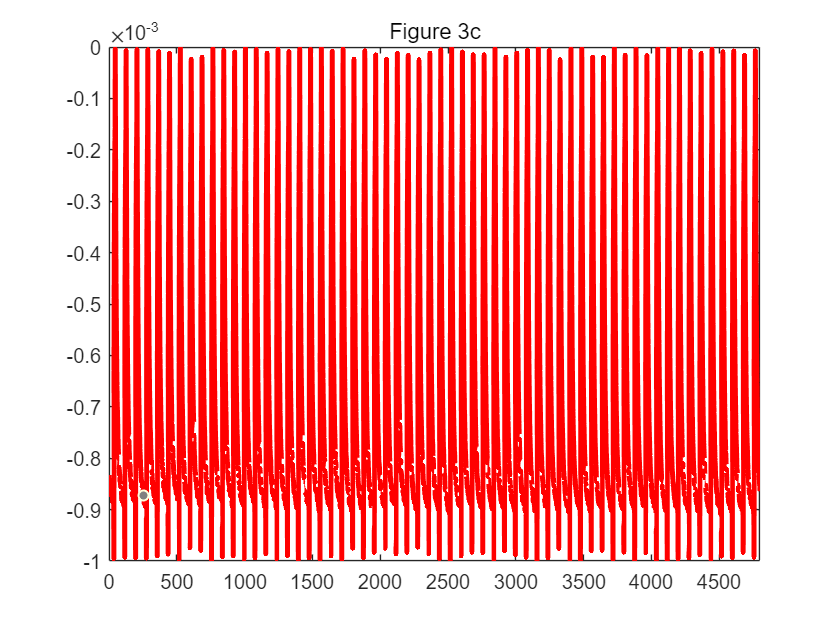

clc; 
clear all;
IdsData = readmatrix("idsdata.xlsx");

figure
plot(IdsData,LineWidth=2.5,Color='r')
xlim([0,4800]);
title('Figure 3c');

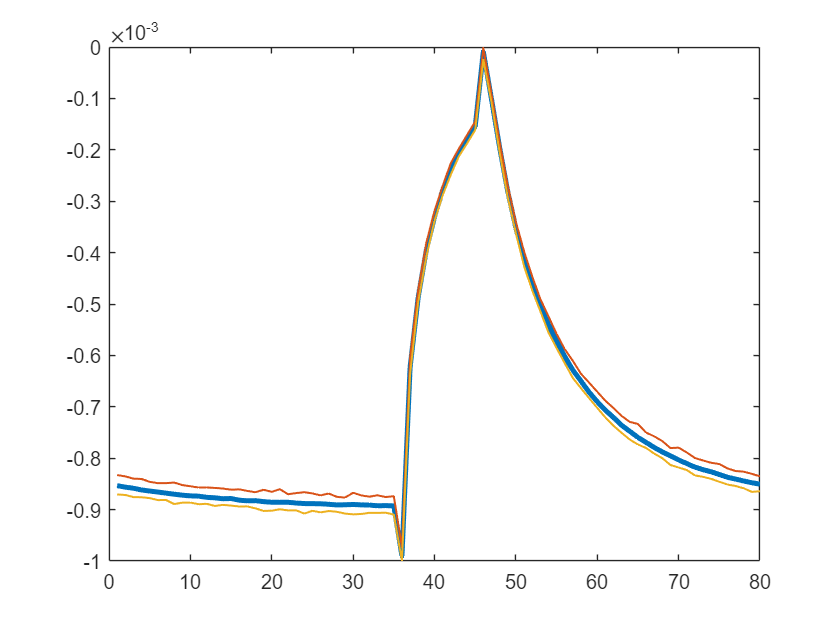

IdsDataReshape = reshape(IdsData,80,60);
IdsDataReshapeAvg = mean(IdsDataReshape,2);
IdsDataReshapeMax = max(IdsDataReshape,[],2);
IdsDataReshapeMin = min(IdsDataReshape,[],2);

figure
plot(IdsDataReshapeAvg,LineWidth=2.5); hold on;
plot(IdsDataReshapeMax,LineWidth=1); hold on;
plot(IdsDataReshapeMin,LineWidth=1);

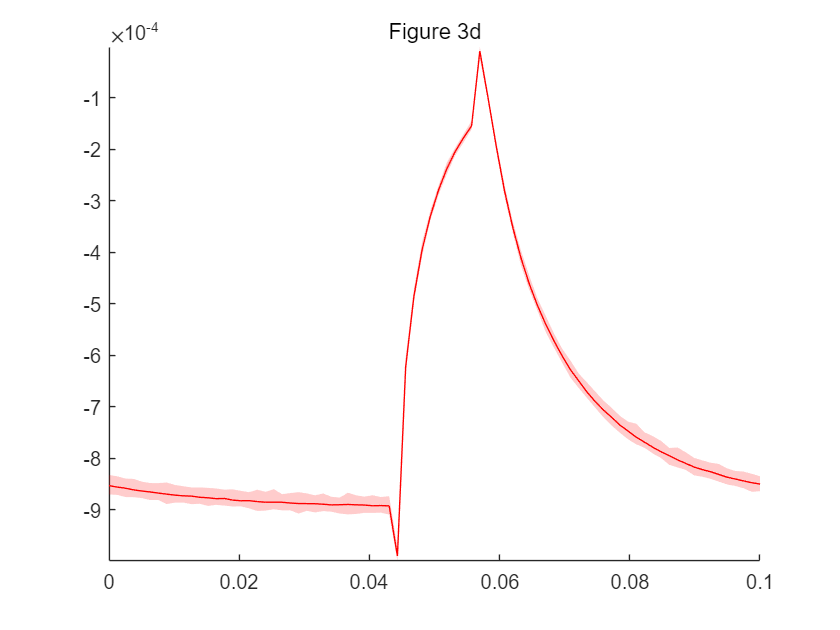

x = linspace(0, 0.1, 80);
e = [IdsDataReshapeAvg-IdsDataReshapeMin IdsDataReshapeMax-IdsDataReshapeAvg];
figure
boundedline(x, IdsDataReshapeAvg, e, 'alpha','r');
title('Figure 3d');
axis tight;